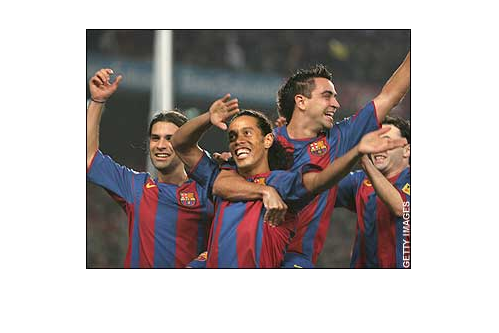

clear all
image=imread('14.jpg');
image=double(image);
figure,imshow(uint8(image))

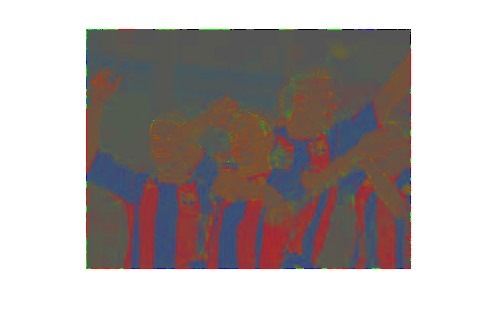


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

for y = 1:row 
    for x = 1:col 
      Red = Image_red(y,x);
      Green = Image_green(y,x);
      Blue = Image_blue(y,x);
    
      NormalizedRed = Red/(Red + Green + Blue);
      NormalizedGreen = Green/(Red + Green + Blue);
      NormalizedBlue = Blue/(Red + Green + Blue);
    
      Image_red(y,x) = NormalizedRed;
      Image_green(y,x) = NormalizedGreen;
      Image_blue(y,x) = NormalizedBlue;
    end
end
image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

figure; imshow(uint8(255*image));

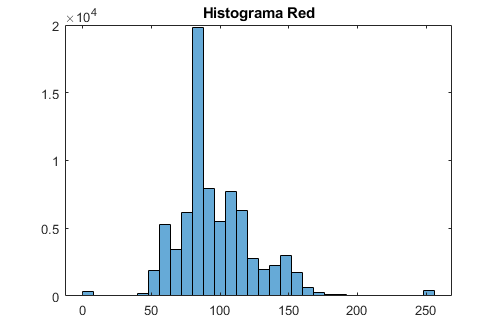


% histogram(image, nBins)
histogram(Image_red*255,32), title('Histograma Red')

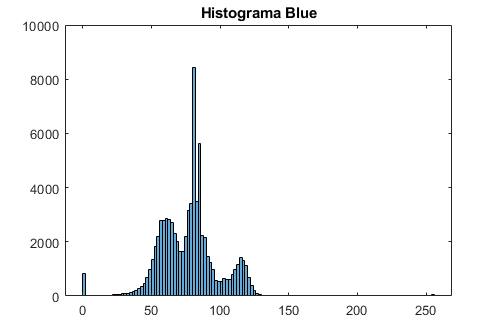

histogram(Image_blue*255), title('Histograma Blue')